Let's start by creating some data on which to perform inference.

rng(14);
n=500;
% rand1 = exprnd(.16,[1,floor(n/3)]);
% rand1 = rand1(rand1<=0.6);
% rand1 = rand1(rand1>0);
% rand3 = exprnd(0.12,[1,floor(n/3)])+0.5;
% rand3 = rand3(rand3<=1);
% rand3 = rand3(rand3>0.5);
lower = 0;
peak = 0.5;
upper = 1;
pd = makedist('Triangular','A',lower,'B',peak,'C',upper);
y = random(pd,1,n);

% y = ([rand1])

% y = y(y<=1);
sum(y<0)

ans = 0

sum(y>1)

ans = 0


% knots = [-0.5, 0.0, 0.1, 0.21, 0.31, 0.41, 0.51, 0.6, 0.71, 0.81, 0.91, 1, 1.5];
% d = 11;
knots = -0.05:0.05:1.05;
constraintFunc = @(x) logspline_constraint(knots, x);
options = optimoptions('fsolve','Display','none','TolFun', 1e-10);

flag=11;
solve_this = @(a) (constraintFunc(a));
% initial = [-2, log(2), log(2.7), log(1.8), log(1.3), log(0.7), log(0.4), -2];
initial = [log(0.005), log(0.25), log(0.6), log(1.7),log(2.3), log(2.2), log(3.1),...
            log(2.4), log(1.4), log(1.6), log(1.2),log(0.7),log(1), log(0.9),...
            log(0.7),log(0.9), log(0.4), log(0.3), log(0.2), log(0.01), -12];
% initial = [-2, log(1), log(2), log(1), log(0.9), log(0.7), log(0.4), -2];
initial_guess = fsolve(solve_this, initial, options)

initial_guess =    -5.2989   -1.3954   -0.5385    0.4661    0.7431    0.6914    1.0156    0.7798    0.2713    0.4082    0.1339   -0.3906   -0.0385   -0.1419   -0.3883   -0.1371   -0.9350   -1.2163   -1.6161   -4.6060  -12.0000



syms func2(x)
chosen_theta = initial_guess

chosen_theta =    -5.2989   -1.3954   -0.5385    0.4661    0.7431    0.6914    1.0156    0.7798    0.2713    0.4082    0.1339   -0.3906   -0.0385   -0.1419   -0.3883   -0.1371   -0.9350   -1.2163   -1.6161   -4.6060  -12.0000


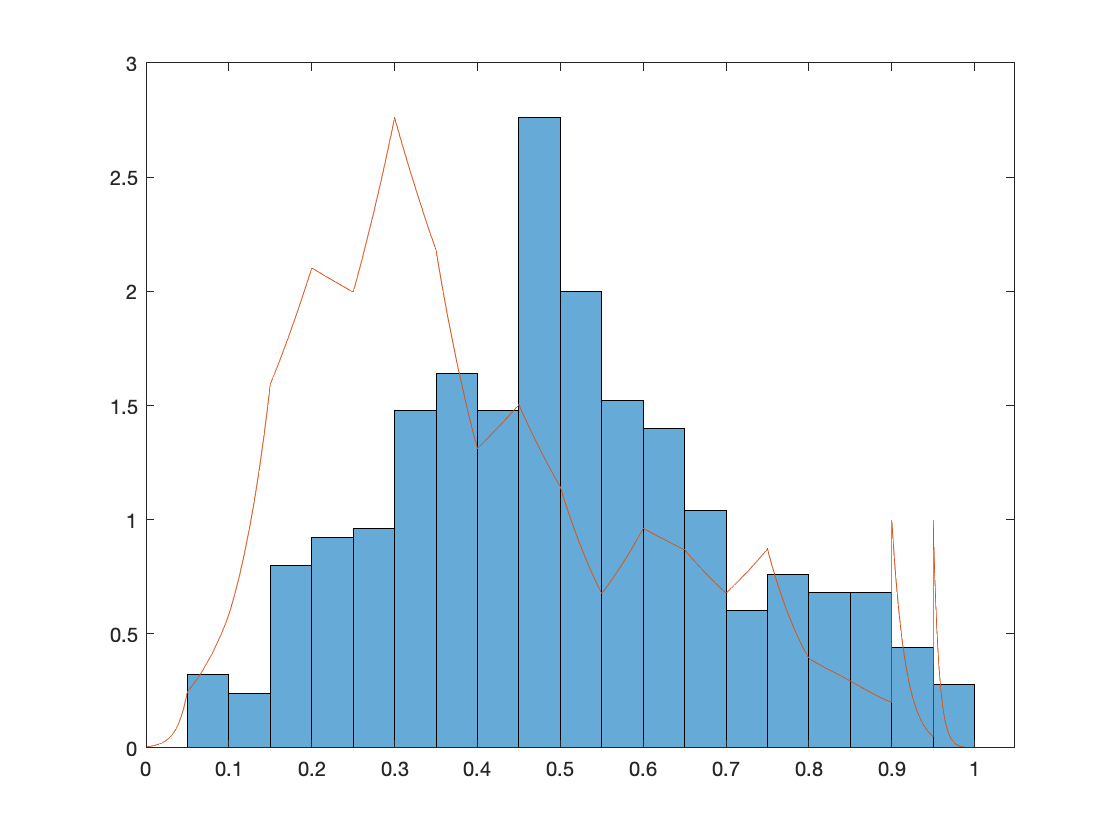

func2(x) = piecewise((knots(2) < x)&(x <= knots(3)),exp(chosen_theta(2)*(x-knots(2))/(knots(3)-knots(2)) + chosen_theta(1)*(knots(3)-x)/(knots(3)-knots(2))), ...
                    (knots(3) < x)&(x <= knots(4)),exp(chosen_theta(3)*(x-knots(3))/(knots(4)-knots(3)) + chosen_theta(2)*(knots(4)-x)/(knots(4)-knots(3))), ...
                    (knots(4) < x)&(x <= knots(5)),exp(chosen_theta(4)*(x-knots(4))/(knots(5)-knots(4)) + chosen_theta(3)*(knots(5)-x)/(knots(5)-knots(4))), ...
                    (knots(5) < x)&(x <= knots(6)),exp(chosen_theta(5)*(x-knots(5))/(knots(6)-knots(5)) + chosen_theta(4)*(knots(6)-x)/(knots(6)-knots(5))), ...
                    (knots(6) < x)&(x <= knots(7)),exp(chosen_theta(6)*(x-knots(6))/(knots(7)-knots(6)) + chosen_theta(5)*(knots(7)-x)/(knots(7)-knots(6))), ...
                    (knots(7) < x)&(x <= knots(8)),exp(chosen_theta(7)*(x-knots(7))/(knots(8)-knots(7)) + chosen_theta(6)*(knots(8)-x)/(knots(8)-knots(7))), ...
                    (knots(8) < x)&(x <= knots(9)),exp(chosen_theta(8)*(x-knots(8))/(knots(9)-knots(8)) + chosen_theta(7)*(knots(9)-x)/(knots(9)-knots(8))), ...
                    (knots(9) < x)&(x <= knots(10)),exp(chosen_theta(9)*(x-knots(9))/(knots(10)-knots(9)) + chosen_theta(8)*(knots(10)-x)/(knots(10)-knots(9))), ...
                    (knots(10) < x)&(x <= knots(11)),exp(chosen_theta(10)*(x-knots(10))/(knots(11)-knots(10)) + chosen_theta(9)*(knots(11)-x)/(knots(11)-knots(10))), ...
                    (knots(11) < x)&(x <= knots(12)),exp(chosen_theta(11)*(x-knots(11))/(knots(12)-knots(11)) + chosen_theta(10)*(knots(12)-x)/(knots(12)-knots(11))), ...
                    (knots(12) < x)&(x <= knots(13)),exp(chosen_theta(12)*(x-knots(12))/(knots(13)-knots(12)) + chosen_theta(11)*(knots(13)-x)/(knots(13)-knots(12))), ...
                    (knots(13) < x)&(x <= knots(14)),exp(chosen_theta(13)*(x-knots(13))/(knots(14)-knots(13)) + chosen_theta(12)*(knots(14)-x)/(knots(14)-knots(13))), ...
                    (knots(14) < x)&(x <= knots(15)),exp(chosen_theta(14)*(x-knots(14))/(knots(15)-knots(14)) + chosen_theta(13)*(knots(15)-x)/(knots(15)-knots(14))), ...
                    (knots(15) < x)&(x <= knots(16)),exp(chosen_theta(15)*(x-knots(15))/(knots(16)-knots(15)) + chosen_theta(14)*(knots(16)-x)/(knots(16)-knots(15))), ...
                    (knots(16) < x)&(x <= knots(17)),exp(chosen_theta(16)*(x-knots(16))/(knots(17)-knots(16)) + chosen_theta(15)*(knots(17)-x)/(knots(17)-knots(16))), ...
                    (knots(17) < x)&(x <= knots(18)),exp(chosen_theta(17)*(x-knots(17))/(knots(18)-knots(17)) + chosen_theta(16)*(knots(18)-x)/(knots(18)-knots(17))), ...
                    (knots(18) < x)&(x <= knots(19)),exp(chosen_theta(18)*(x-knots(18))/(knots(19)-knots(18)) + chosen_theta(17)*(knots(19)-x)/(knots(19)-knots(18))), ...
                    (knots(19) < x)&(x <= knots(20)),exp(chosen_theta(19)*(x-knots(19))/(knots(20)-knots(19)) + chosen_theta(18)*(knots(20)-x)/(knots(20)-knots(19))), ...
                    (knots(20) < x)&(x <= knots(21)),exp(chosen_theta(20)*(x-knots(20))/(knots(21)-knots(20)) + chosen_theta(19)*(knots(20)-x)/(knots(20)-knots(19))), ...
                    (knots(21) < x)&(x <= knots(22)),exp(chosen_theta(21)*(x-knots(21))/(knots(22)-knots(21)) + chosen_theta(20)*(knots(21)-x)/(knots(21)-knots(20))));
histogram(y, 'Normalization','pdf','BinWidth',0.05)
hold on
fplot(func2, [0,1])
hold off

We'll select knots based on the graphic, although more principled methods exist.

% Arbitrarily choosing the starting value, with dimension parameter_dim:
data = y;
q0 = initial_guess';
nllFunc = @(x) negLog_fiducial_likelihood(knots,x,data);
conFunc = constraintFunc;

% Set parameters (that I don't quite understand)
nRuns = 1+10;
Nscale = 700;
runTime = 15; % Time per run in seconds
nTrials = 100;
doPrint = false;

samplers = struct([]);

h = 9e-5;
M = 1;
L = 2;
hmcOpts = struct('intMethod',0,'doPrint',doPrint,'printMod',10);
samplers(end+1).name = sprintf('CHMC (L = %d)',L);
samplers(end).desc = sprintf('M = %g, h = %g',M,h);
samplers(end).func = @(q,N) constrainedHMC(q,nllFunc,conFunc,M,N,L,h,hmcOpts);
samplers(end).N = ceil(Nscale./L);
samplers(end).style = 'b-';

samplerQs = cell(length(samplers),1+nTrials);
samplerStats = cell(length(samplers),1+nTrials);
samplerNLLs = cell(length(samplers),1+nTrials);
samplerTs = zeros(length(samplers),1+nTrials);
for i = 1:numel(samplers)
    fprintf('%s...',samplers(i).name);
    [q1,qs,samplerStats{i,1}] = samplers(i).func(q0,samplers(i).N);
    samplerQs{i,1} = [q0 qs q1];
    samplerTs(i,1) = samplerStats{i,1}.t/samplerStats{i,1}.N;
%     samplerNLLs{i,1} = nllFunc(samplerQs{i,1});
    
    currN = ceil(runTime./samplerTs(i,1));
    fprintf('%d samples: ',currN);
    fprintf('\n');
end

CHMC (L = 2)...

Performing a total of 350 iterations.
1
2
3
4
5
6
7
8
9
10
11
12
13
14
15
16
17
18
19
20
21
22
23
24
25
26
27
28
29
30
31
32
33
34
35
36
37
38
39
40
41
42
43
44
45
46
47
48
49
50
51
52
53
54
55
56
57
58
59
60
61
62
63
64
65
66
67
68
69
70
71
72
73
74
75
76
77
78
79
80
81
82
83
84
85
86
87
88
89
90
91
92
93
94
95
96
97
98
99
100
101
102
103
104
105
106
107
108
109
110
111
112
113
114
115
116
117
118
119
120
121
122
123
124
125
126
127
128
129
130
131
132
133
134
135
136
137
138
139
140
141
142
143
144
145
146
147
148
149
150
151
152
153
154
155
156
157
158
159
160
161
162
163
164
165
166
167
168
169
170
171
172
173
174
175
176
177
178
179
180
181
182
183
184
185
186
187
188
189
190
191
192
193
194
195
196
197
198
199
200
201
202
203
204
205
206
207
208
209
210
211
212
213
214
215
216
217
218
219
220
221
222
223
224
225
226
227
228
229
230
231
232
233
234
235
236
237
238
239
240
241
242
243
244
245
246
247
248
249
250
251
252
253
254
255
256
257
258
259
260
261
262
263
264
265
266
267
26

17 samples: 

mean(samplerStats{1,1}.accepted)

ans = 0.7000

Qs = samplerQs{1,1};
save("HMC_logsplineDraws.mat",'Qs');

Qs = load("HMC_logsplineDraws.mat").Qs

Qs =    -2.0219   -2.0219   -2.0218   -2.0216   -2.0213   -2.0213   -2.0213   -2.0212   -2.0212   -2.0213   -2.0215   -2.0214   -2.0214   -2.0214   -2.0214   -2.0214   -2.0215   -2.0213   -2.0209   -2.0206   -2.0206   -2.0203   -2.0203   -2.0203   -2.0203   -2.0203   -2.0203   -2.0201   -2.0203   -2.0200   -2.0200   -2.0200   -2.0200   -2.0200   -2.0199   -2.0198   -2.0196   -2.0196   -2.0196   -2.0194   -2.0193   -2.0198   -2.0196   -2.0195   -2.0195   -2.0195   -2.0197   -2.0196   -2.0201   -2.0201
    0.4684    0.4684    0.4686    0.4684    0.4683    0.4683    0.4683    0.4684    0.4684    0.4686    0.4686    0.4687    0.4687    0.4687    0.4687    0.4687    0.4684    0.4685    0.4686    0.4688    0.4688    0.4688    0.4688    0.4688    0.4688    0.4686    0.4688    0.4690    0.4693    0.4698    0.4698    0.4698    0.4698    0.4698    0.4702    0.4701    0.4701    0.4699    0.4699    0.4698    0.4699    0.4702    0.4700    0.4700    0.4700    0.4702    0.4700    0.4702    0.4702    


samples = Qs;
mean_value = mean(samples')';
mean_diff = samples - mean_value;
[~,num_cols] = size(mean_diff);
mag_mean_diff = zeros(1,num_cols);
for i=1:num_cols
    mag_mean_diff(i) = norm(mean_diff(:,i), 2);
end
[~,min_index] = min(mag_mean_diff);

chosen_theta = samples(:,350)

chosen_theta =    -2.0200
    0.4671
    0.9250
    0.7363
    0.1616
    0.4058
   -0.3238
   -0.1825
   -2.3245
   -2.0138



syms func1(x)
% func(x) = piecewise((knots(2) < x)&(x <= knots(3)),exp(chosen_theta(2)*(x-knots(2))/(knots(3)-knots(2)) + chosen_theta(1)*(knots(3)-x)/(knots(3)-knots(2))), ...
%                     (knots(3) < x)&(x <= knots(4)),exp(chosen_theta(3)*(x-knots(3))/(knots(4)-knots(3)) + chosen_theta(2)*(knots(4)-x)/(knots(4)-knots(3))), ...
%                     (knots(4) < x)&(x <= knots(5)),exp(chosen_theta(4)*(x-knots(4))/(knots(5)-knots(4)) + chosen_theta(3)*(knots(5)-x)/(knots(5)-knots(4))), ...
%                     (knots(5) < x)&(x <= knots(6)),exp(chosen_theta(5)*(x-knots(5))/(knots(6)-knots(5)) + chosen_theta(4)*(knots(6)-x)/(knots(6)-knots(5))), ...
%                     (knots(6) < x)&(x <= knots(7)),exp(chosen_theta(6)*(x-knots(7))/(knots(7)-knots(6)) + chosen_theta(5)*(knots(7)-x)/(knots(7)-knots(6))), ...
%                     (knots(7) < x)&(x <= knots(8)),exp(chosen_theta(7)*(x-knots(8))/(knots(8)-knots(7)) + chosen_theta(6)*(knots(8)-x)/(knots(8)-knots(7))), ...
%                     (knots(8) < x)&(x <= knots(9)),exp(chosen_theta(8)*(x-knots(9))/(knots(9)-knots(8)) + chosen_theta(7)*(knots(9)-x)/(knots(9)-knots(8))), ...
%                     (knots(9) < x)&(x <= knots(10)),exp(chosen_theta(9)*(x-knots(10))/(knots(10)-knots(9)) + chosen_theta(8)*(knots(10)-x)/(knots(10)-knots(9))), ...
%                     (knots(10) < x)&(x <= knots(11)),exp(chosen_theta(10)*(x-knots(11))/(knots(11)-knots(10)) + chosen_theta(9)*(knots(11)-x)/(knots(11)-knots(10))), ...
%                     (knots(11) < x)&(x <= knots(12)),exp(chosen_theta(11)*(x-knots(12))/(knots(12)-knots(11)) + chosen_theta(10)*(knots(12)-x)/(knots(12)-knots(11))) );

func1(x) = piecewise((knots(2) < x)&(x <= knots(3)),exp(chosen_theta(2)*(x-knots(2))/(knots(3)-knots(2)) + chosen_theta(1)*(knots(3)-x)/(knots(3)-knots(2))), ...
                    (knots(3) < x)&(x <= knots(4)),exp(chosen_theta(3)*(x-knots(3))/(knots(4)-knots(3)) + chosen_theta(2)*(knots(4)-x)/(knots(4)-knots(3))), ...
                    (knots(4) < x)&(x <= knots(5)),exp(chosen_theta(4)*(x-knots(4))/(knots(5)-knots(4)) + chosen_theta(3)*(knots(5)-x)/(knots(5)-knots(4))), ...
                    (knots(5) < x)&(x <= knots(6)),exp(chosen_theta(5)*(x-knots(5))/(knots(6)-knots(5)) + chosen_theta(4)*(knots(6)-x)/(knots(6)-knots(5))), ...
                    (knots(6) < x)&(x <= knots(7)),exp(chosen_theta(6)*(x-knots(6))/(knots(7)-knots(6)) + chosen_theta(5)*(knots(7)-x)/(knots(7)-knots(6))), ...
                    (knots(7) < x)&(x <= knots(8)),exp(chosen_theta(7)*(x-knots(7))/(knots(8)-knots(7)) + chosen_theta(6)*(knots(8)-x)/(knots(8)-knots(7))), ...
                    (knots(8) < x)&(x <= knots(9)),exp(chosen_theta(8)*(x-knots(8))/(knots(9)-knots(8)) + chosen_theta(7)*(knots(9)-x)/(knots(9)-knots(8))), ...
                    (knots(9) < x)&(x <= knots(10)),exp(chosen_theta(9)*(x-knots(9))/(knots(10)-knots(9)) + chosen_theta(8)*(knots(10)-x)/(knots(10)-knots(9))), ...
                    (knots(10) < x)&(x <= knots(11)),exp(chosen_theta(10)*(x-knots(10))/(knots(11)-knots(10)) + chosen_theta(9)*(knots(11)-x)/(knots(11)-knots(10))), ...
                    (knots(11) < x)&(x <= knots(12)),exp(chosen_theta(11)*(x-knots(11))/(knots(12)-knots(11)) + chosen_theta(10)*(knots(12)-x)/(knots(12)-knots(11))), ...
                    (knots(12) < x)&(x <= knots(13)),exp(chosen_theta(12)*(x-knots(12))/(knots(13)-knots(12)) + chosen_theta(11)*(knots(13)-x)/(knots(13)-knots(12))), ...
                    (knots(13) < x)&(x <= knots(14)),exp(chosen_theta(13)*(x-knots(13))/(knots(14)-knots(13)) + chosen_theta(12)*(knots(14)-x)/(knots(14)-knots(13))), ...
                    (knots(14) < x)&(x <= knots(15)),exp(chosen_theta(14)*(x-knots(14))/(knots(15)-knots(14)) + chosen_theta(13)*(knots(15)-x)/(knots(15)-knots(14))), ...
                    (knots(15) < x)&(x <= knots(16)),exp(chosen_theta(15)*(x-knots(15))/(knots(16)-knots(15)) + chosen_theta(14)*(knots(16)-x)/(knots(16)-knots(15))), ...
                    (knots(16) < x)&(x <= knots(17)),exp(chosen_theta(16)*(x-knots(16))/(knots(17)-knots(16)) + chosen_theta(15)*(knots(17)-x)/(knots(17)-knots(16))), ...
                    (knots(17) < x)&(x <= knots(18)),exp(chosen_theta(17)*(x-knots(17))/(knots(18)-knots(17)) + chosen_theta(16)*(knots(18)-x)/(knots(18)-knots(17))), ...
                    (knots(18) < x)&(x <= knots(19)),exp(chosen_theta(18)*(x-knots(18))/(knots(19)-knots(18)) + chosen_theta(17)*(knots(19)-x)/(knots(19)-knots(18))), ...
                    (knots(19) < x)&(x <= knots(20)),exp(chosen_theta(19)*(x-knots(19))/(knots(20)-knots(19)) + chosen_theta(18)*(knots(20)-x)/(knots(20)-knots(19))), ...
                    (knots(20) < x)&(x <= knots(21)),exp(chosen_theta(20)*(x-knots(20))/(knots(21)-knots(20)) + chosen_theta(19)*(knots(20)-x)/(knots(20)-knots(19))), ...
                    (knots(21) < x)&(x <= knots(22)),exp(chosen_theta(21)*(x-knots(21))/(knots(22)-knots(21)) + chosen_theta(20)*(knots(21)-x)/(knots(21)-knots(20))));
syms func2(x)
chosen_theta = samples(:,1)

chosen_theta =    -2.0219
    0.4684
    0.9262
    0.7330
    0.1628
    0.4040
   -0.3196
   -0.1874
   -2.3250
   -2.0119


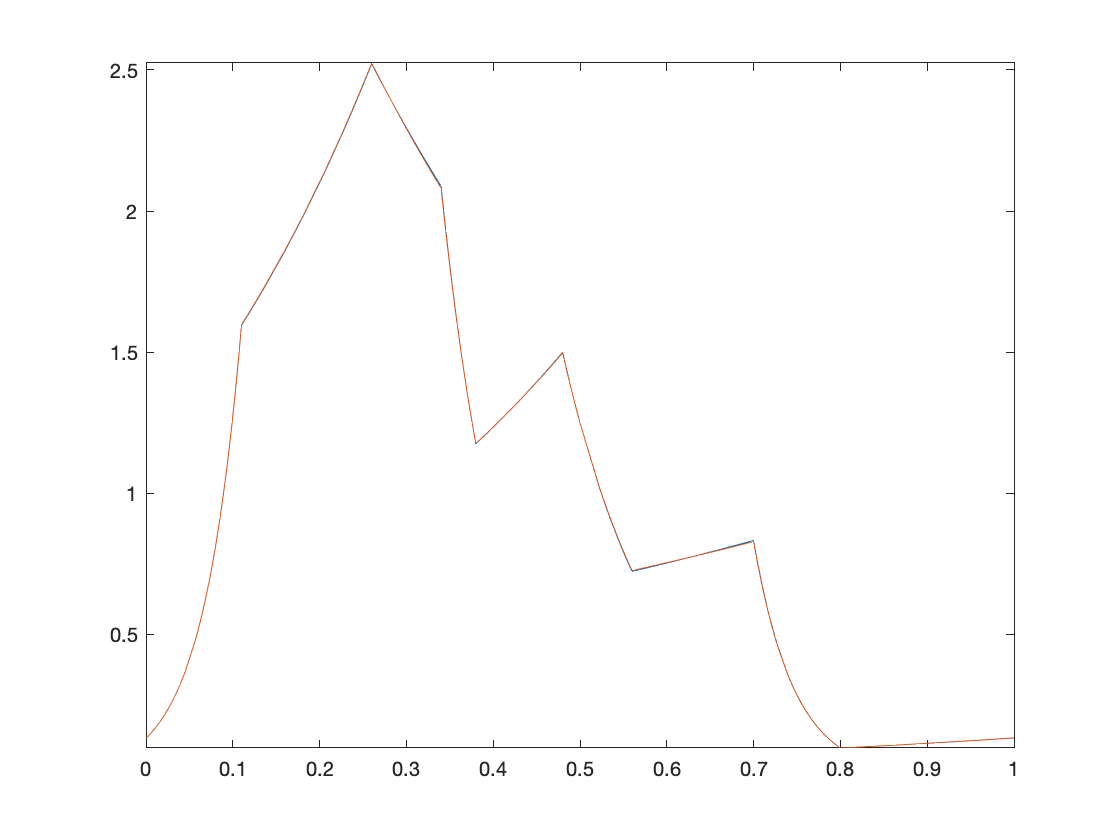

func2(x) = piecewise((knots(2) < x)&(x <= knots(3)),exp(chosen_theta(2)*(x-knots(2))/(knots(3)-knots(2)) + chosen_theta(1)*(knots(3)-x)/(knots(3)-knots(2))), ...
                    (knots(3) < x)&(x <= knots(4)),exp(chosen_theta(3)*(x-knots(3))/(knots(4)-knots(3)) + chosen_theta(2)*(knots(4)-x)/(knots(4)-knots(3))), ...
                    (knots(4) < x)&(x <= knots(5)),exp(chosen_theta(4)*(x-knots(4))/(knots(5)-knots(4)) + chosen_theta(3)*(knots(5)-x)/(knots(5)-knots(4))), ...
                    (knots(5) < x)&(x <= knots(6)),exp(chosen_theta(5)*(x-knots(5))/(knots(6)-knots(5)) + chosen_theta(4)*(knots(6)-x)/(knots(6)-knots(5))), ...
                    (knots(6) < x)&(x <= knots(7)),exp(chosen_theta(6)*(x-knots(6))/(knots(7)-knots(6)) + chosen_theta(5)*(knots(7)-x)/(knots(7)-knots(6))), ...
                    (knots(7) < x)&(x <= knots(8)),exp(chosen_theta(7)*(x-knots(7))/(knots(8)-knots(7)) + chosen_theta(6)*(knots(8)-x)/(knots(8)-knots(7))), ...
                    (knots(8) < x)&(x <= knots(9)),exp(chosen_theta(8)*(x-knots(8))/(knots(9)-knots(8)) + chosen_theta(7)*(knots(9)-x)/(knots(9)-knots(8))), ...
                    (knots(9) < x)&(x <= knots(10)),exp(chosen_theta(9)*(x-knots(9))/(knots(10)-knots(9)) + chosen_theta(8)*(knots(10)-x)/(knots(10)-knots(9))), ...
                    (knots(10) < x)&(x <= knots(11)),exp(chosen_theta(10)*(x-knots(10))/(knots(11)-knots(10)) + chosen_theta(9)*(knots(11)-x)/(knots(11)-knots(10))), ...
                    (knots(11) < x)&(x <= knots(12)),exp(chosen_theta(11)*(x-knots(11))/(knots(12)-knots(11)) + chosen_theta(10)*(knots(12)-x)/(knots(12)-knots(11))), ...
                    (knots(12) < x)&(x <= knots(13)),exp(chosen_theta(12)*(x-knots(12))/(knots(13)-knots(12)) + chosen_theta(11)*(knots(13)-x)/(knots(13)-knots(12))), ...
                    (knots(13) < x)&(x <= knots(14)),exp(chosen_theta(13)*(x-knots(13))/(knots(14)-knots(13)) + chosen_theta(12)*(knots(14)-x)/(knots(14)-knots(13))), ...
                    (knots(14) < x)&(x <= knots(15)),exp(chosen_theta(14)*(x-knots(14))/(knots(15)-knots(14)) + chosen_theta(13)*(knots(15)-x)/(knots(15)-knots(14))), ...
                    (knots(15) < x)&(x <= knots(16)),exp(chosen_theta(15)*(x-knots(15))/(knots(16)-knots(15)) + chosen_theta(14)*(knots(16)-x)/(knots(16)-knots(15))), ...
                    (knots(16) < x)&(x <= knots(17)),exp(chosen_theta(16)*(x-knots(16))/(knots(17)-knots(16)) + chosen_theta(15)*(knots(17)-x)/(knots(17)-knots(16))), ...
                    (knots(17) < x)&(x <= knots(18)),exp(chosen_theta(17)*(x-knots(17))/(knots(18)-knots(17)) + chosen_theta(16)*(knots(18)-x)/(knots(18)-knots(17))), ...
                    (knots(18) < x)&(x <= knots(19)),exp(chosen_theta(18)*(x-knots(18))/(knots(19)-knots(18)) + chosen_theta(17)*(knots(19)-x)/(knots(19)-knots(18))), ...
                    (knots(19) < x)&(x <= knots(20)),exp(chosen_theta(19)*(x-knots(19))/(knots(20)-knots(19)) + chosen_theta(18)*(knots(20)-x)/(knots(20)-knots(19))), ...
                    (knots(20) < x)&(x <= knots(21)),exp(chosen_theta(20)*(x-knots(20))/(knots(21)-knots(20)) + chosen_theta(19)*(knots(20)-x)/(knots(20)-knots(19))), ...
                    (knots(21) < x)&(x <= knots(22)),exp(chosen_theta(21)*(x-knots(21))/(knots(22)-knots(21)) + chosen_theta(20)*(knots(21)-x)/(knots(21)-knots(20))));

% fplot(y, [0,1])

fplot(func1, [0,1])
hold on
fplot(func2, [0,1])
hold off


% double(int(func1, 0, 1))
% double(int(f, 0, 1))